
% Questão 1
id = 3;
k = 19;
z = tf('z',0.1);
g = k*(z*z + id*id)/((z-0.5)^3) % FTMA do sistema com RU

g =
 
           19 z^2 + 171
  ------------------------------
  z^3 - 1.5 z^2 + 0.75 z - 0.125
 
Sample time: 0.1 seconds
Discrete-time transfer function.



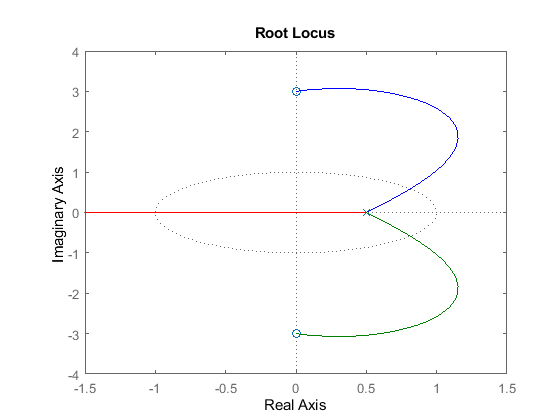

rlocus(g)

% Ângulo de quebra = (2q+1)*180/(#polos-#zeros)
% Ângulo de quebra = (2*0+1)*180/(3-2) = 180
% Centroide = (sum(real(polos))- sum(real(zero)))/(#polos - #zeros)
% Centroide = ((0.5) - (0))/(3 - 2) = 0.5
% O que diabos é xjw?

% Questão 2
k2 = 19;
g2 = zpk([-1],[0-1*i 0+1*i 0 1],k2)

g2 =
 
      19 (s+1)
  -----------------
  s (s-1) (s^2 + 1)
 
Continuous-time zero/pole/gain model.



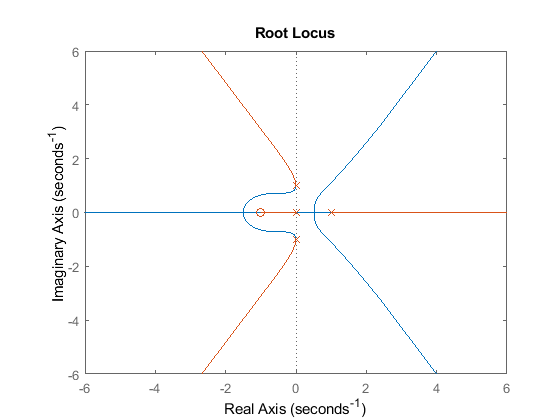

rlocus(g2,-g2)

%rlocus(-g2)

% Questão 3
% Sistema coma RNU, ordem 4, dois zeros em MA
% Como eu deveria fazer isso no matlab, meu fi?
k3 = 19;
g3 = zpk([-0.5 -0.5],[-0.2 -0.2 -0.7 -0.7],k3)

g3 =
 
     19 (s+0.5)^2
  -------------------
  (s+0.2)^2 (s+0.7)^2
 
Continuous-time zero/pole/gain model.



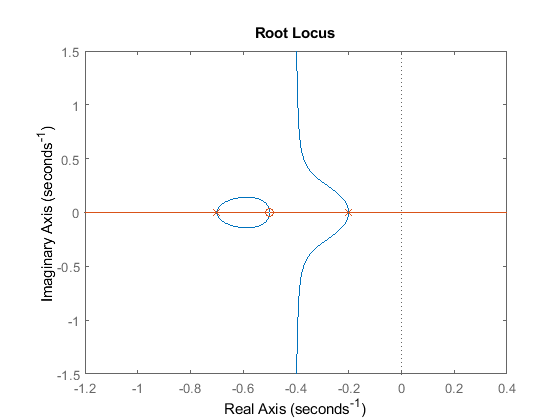

rlocus(g3,-g3)

% Questão 4
% Ângulo de quebra = (2q+1)*180/(#polos-#zeros)
% Centroide = (sum(real(polos))- sum(real(zero)))/(#polos - #zeros)
id = 3;
k = 29;
s = tf('s');
% a e b são FTMA SC RNU
a = k*((s+id)^2)/(s^2 -2*s + 2)

a =
 
  29 s^2 + 174 s + 261
  --------------------
     s^2 - 2 s + 2
 
Continuous-time transfer function.



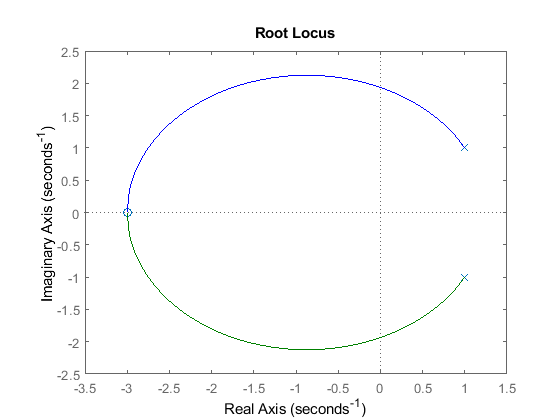

rlocus(a)%;grid;

% A - Sem Ângulo de quebra ou centroide, pois não há assíntota (pois não há componente
% sem par)
b = k*(s+2*id)/( (s^2 + id^2)*((s + id)^2) )

b =
 
             29 s + 174
  --------------------------------
  s^4 + 6 s^3 + 18 s^2 + 54 s + 81
 
Continuous-time transfer function.



pole(b)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
  -3.0000 + 0.0000i
  -3.0000 - 0.0000i


zero(b)

ans = -6

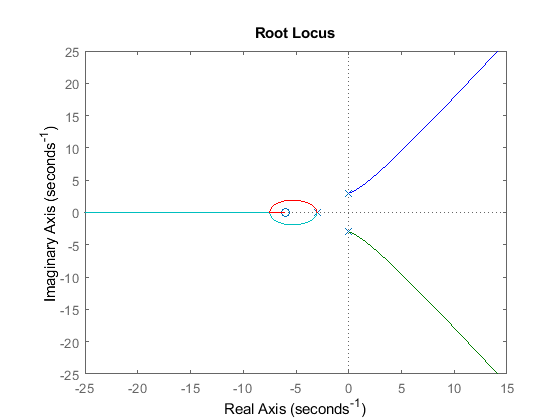

rlocus(b)%;grid;

% B - Ângulo de quebra = (2*0+1)*180/(4-1) = 60°, (2*1+1)*60 = 180°,
% (2*2+1)*60 = 300°
% B - Centroide = (-6 - (-6))/(4-1) = 0 (?)
% rlocus(a,b);grid;



